# 3.1 分布の特徴をとらえる

### 図 3.1.1 基本的な分布の特徴

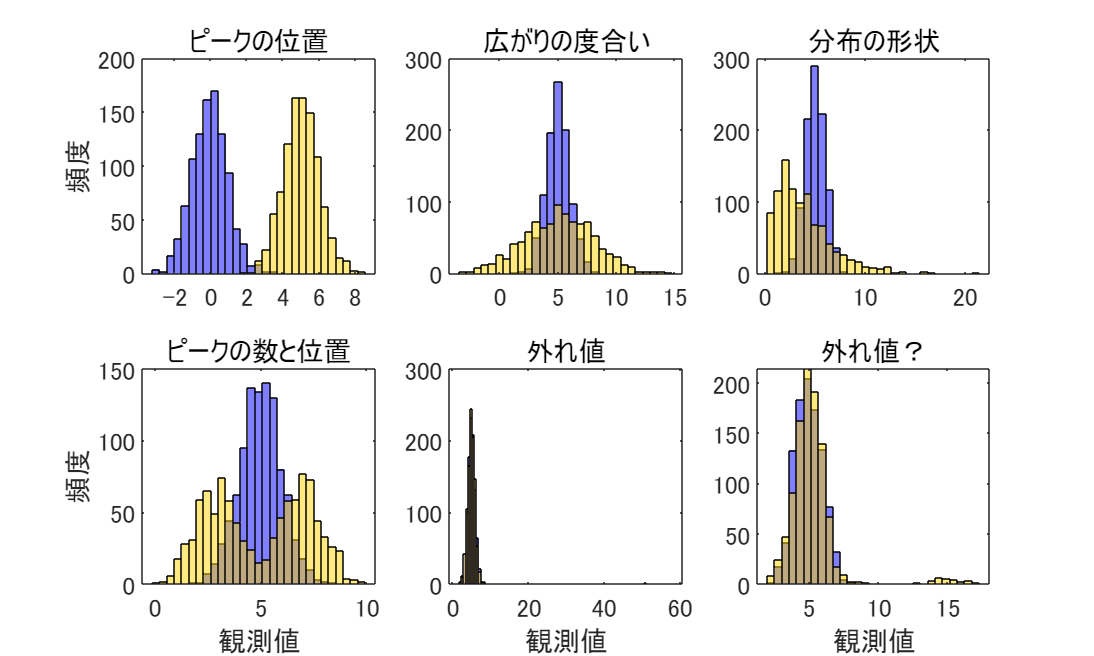

% フォントサイズを設定
set(0, 'DefaultAxesFontSize', 14);

% 再現性のため乱数シードを設定
rng(0);

% 中央傾向：平均が0と5の正規分布からデータを生成
data1_a = normrnd(0, 1, [1000, 1]);
data1_b = normrnd(5, 1, [1000, 1]);

% 分散：標準偏差が1と3の正規分布からデータを生成
data2_a = normrnd(5, 1, [1000, 1]);
data2_b = normrnd(5, 3, [1000, 1]);

% 形状：正規分布とガンマ分布からデータを生成
data3_a = normrnd(5, 1, [1000, 1]);
data3_b = gamrnd(2, 2, [1000, 1]);

% ピーク：単一ピークと二重ピークの正規分布からデータを生成
data4_a = normrnd(5, 1, [1000, 1]);
data4_b = [normrnd(3, 1, [500, 1]); normrnd(7, 1, [500, 1])];

% 外れ値：外れ値を含む分布と含まない分布からデータを生成
data5_a = [normrnd(5, 1, [995, 1]); normrnd(50, 5, [5, 1])];
data5_b = normrnd(5, 1, [1000, 1]);

% 外れ値：外れ値がある分布と少ない分布からデータを生成
data6_a = normrnd(5, 1, [1000, 1]);
data6_b = [normrnd(5, 1, [975, 1]); normrnd(15, 1, [25, 1])];

% データを配列に格納
data_a = {data1_a, data2_a, data3_a, data4_a, data5_a, data6_a};
data_b = {data1_b, data2_b, data3_b, data4_b, data5_b, data6_b};

% タイトルを配列に格納
titles = {'ピークの位置', '広がりの度合い', '分布の形状', 'ピークの数と位置', '外れ値', '外れ値？'};

% 2行3列のサブプロットを作成
figure;

% ヒストグラムをプロット
for i = 1:6
    subplot(2, 3, i);
    min_bin = min(min(data_a{i}), min(data_b{i}));
    max_bin = max(max(data_a{i}), max(data_b{i}));
    bins = linspace(min_bin, max_bin, 30);
    if i == 5
        bins = linspace(min_bin, max_bin, 100); % 外れ値のためのビン数を増やす
    end
    
    histogram(data_a{i}, bins, 'FaceColor', 'b', 'EdgeColor', 'k', 'FaceAlpha', 0.5);
    hold on;
    histogram(data_b{i}, bins, 'FaceColor', [1, 0.84, 0], 'EdgeColor', 'k', 'FaceAlpha', 0.5);
    hold off;
    title(titles{i});
    if i == 4 || i == 5 || i == 6
        xlabel('観測値');
    end
    if i == 1 || i == 4
        ylabel('頻度');
    end
end

% レイアウトを調整
set(gcf, 'Position', [100, 100, 1000, 600]); % 図のサイズを調整

% 図をPNGファイルとして保存
print('../figures/3_1_1_dist_comparison','-dpng','-r300'); % dpiを指定して保存

### 図 3.1.2 ヒストグラムの形状とビンの定義

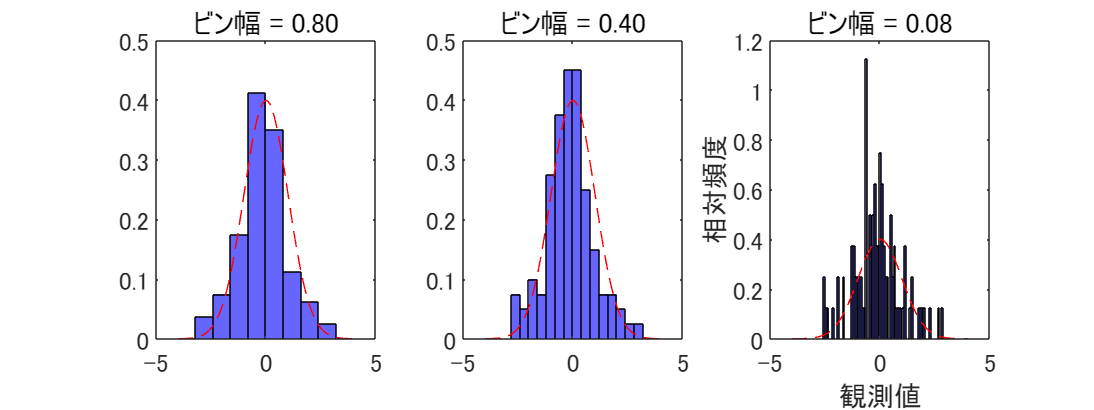

% フォントサイズを設定
% set(0, 'DefaultAxesFontSize', 14);

% 再現性のため乱数シードを設定
rng(2);

% 正規分布から100点をサンプル
mu = 0; % 平均
sigma = 1; % 標準偏差
s = normrnd(mu, sigma, [100, 1]);

% ビンのサイズ
bins_sizes = [5, 10, 50];

% 正規分布のプロット用のデータ
x = linspace(-4, 4, 200);
y = normpdf(x, mu, sigma);

% サブプロットとしてヒストグラムを生成
figure;
for i = 1:length(bins_sizes)
    subplot(1, 3, i);
    histogram(s, 'BinWidth', 4/bins_sizes(i), 'Normalization', 'pdf', 'FaceColor', 'b', 'FaceAlpha', 0.6);
    hold on;
    plot(x, y, 'r--'); % 正規分布を描画
    title(sprintf('ビン幅 = %1.2f', 4/bins_sizes(i)));
    hold off;
end

% ラベルを設定
ylabel('相対頻度');
xlabel('観測値');

% レイアウトの設定
set(gcf, 'Position', [100, 100, 800, 300]);

% 画像として保存
print('../figures/3_1_2_1_bin_size','-dpng','-r300'); % dpiを指定して保存

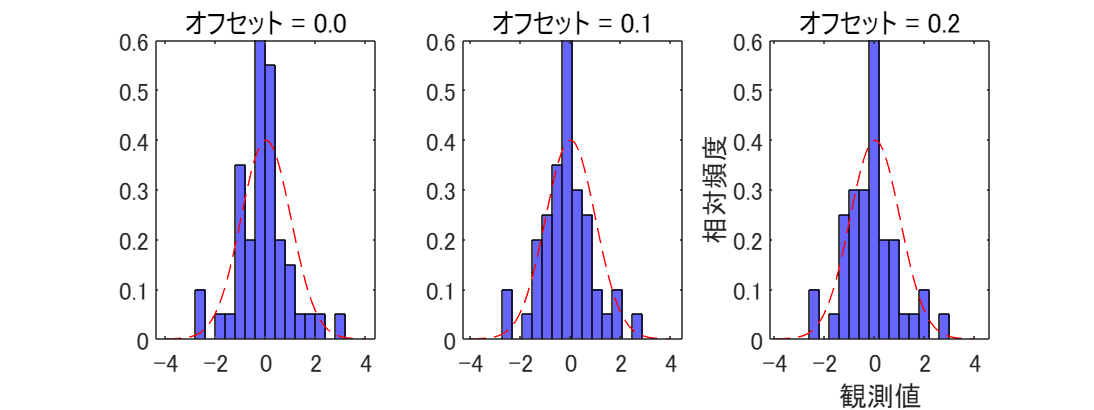

% 再現性のため乱数シードを設定
rng(2);

% 正規分布から50点をサンプル
s = normrnd(mu, sigma, [50, 1]);

% ビンのサイズとオフセット
bins_sizes = [20, 20, 20];
offsets = [0, 0.1, 0.2];

% サブプロットとしてヒストグラムを生成
figure;
for i = 1:length(bins_sizes)
    subplot(1, 3, i);
    bins_list = linspace(-4 + offsets(i), 4 + offsets(i), bins_sizes(i) + 1);
    histogram(s, 'BinEdges', bins_list, 'Normalization', 'pdf', 'FaceColor', 'b', 'FaceAlpha', 0.6);
    hold on;
    plot(x, y, 'r--'); % 正規分布を描画
    ylim([0, 0.6]); % y軸の範囲を設定
    title(sprintf('オフセット = %1.1f', offsets(i)));
    hold off;
end

% ラベルを設定
ylabel('相対頻度');
xlabel('観測値');

% レイアウトの設定
set(gcf, 'Position', [100, 100, 800, 300]);

% 画像として保存
print('../figures/3_1_2_2_bin_offset','-dpng','-r300'); % dpiを指定して保存

% グラフの表示（MATLABでは自動的に表示されます）

### 図 3.1.3 正規分布との比較

% フォントサイズを設定
set(0, 'DefaultAxesFontSize', 14);

% 再現性のため乱数シードを設定
rng(0);

% サイコロを100回振った時の出目の総和を1000回サンプリングする
dice_sums = arrayfun(@(x) roll_dice(), 1:1000, 'UniformOutput', false);
dice_sums = dice_sums(:); % ベクトルに変換

% ヒストグラムを作成
figure; % 図の作成
histogram(dice_sums, 'BinEdges', 280:420, 'Normalization', 'pdf', ...
          'FaceColor', 'w', 'EdgeColor', 'k', 'FaceAlpha', 0.7);

次を使用中のエラー: histogram
1 番目の入力引数 x は以下のいずれかのタイプが必要です:

double, single, uint8, uint16, uint32, uint64, int8, int16, int32, int64, logical, datetime, duration, categorical

実際の型は cell でした。

エラー: histogram>parseinput (行 267)
        validateattributes(x,{'numeric','logical','datetime','duration','categorical'},...

エラー: histogram (


% 正規分布のパラメータを推定
pd = fitdist(dice_sums, 'Normal');
mu = pd.mu; % 平均
std = pd.sigma; % 標準偏差
fprintf('%f %f\n', mu, std);

% 正規分布を描画
xmin = 280;
xmax = 420;
x = linspace(xmin, xmax, 100);
p = normpdf(x, mu, std);

hold on;
plot(x, p, 'r--', 'LineWidth', 2); % 正規分布を描画
xlabel('サイコロを100回振って出た目の総和'); % x軸ラベル
ylabel('相対頻度'); % y軸ラベル

% レイアウトの設定
set(gcf, 'Position', [100, 100, 500, 400]);

% 画像として保存
print('../figures/3_1_3_1_gaussian_fitting','-dpng','-r300'); % dpiを指定して保存


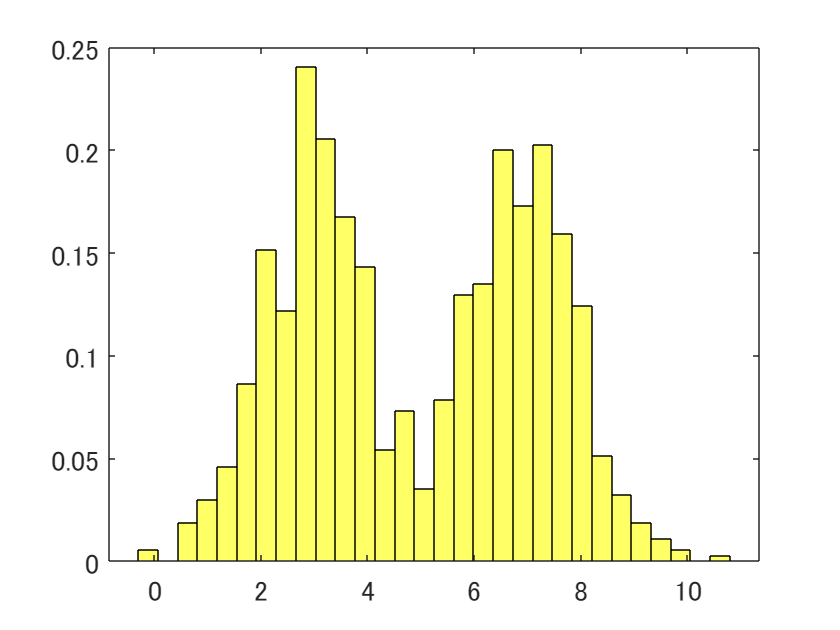

% フォントサイズを設定
set(0, 'DefaultAxesFontSize', 14);

% 再現性のため乱数シードを設定
rng(0);

% ピーク一つとピーク二つの分布
data4_b = [normrnd(3, 1, [500, 1]); normrnd(7, 1, [500, 1])];

% データをヒストグラムでプロット
figure; % グラフのサイズを指定
histogram(data4_b, 30, 'Normalization', 'pdf', 'FaceColor', 'yellow', 'EdgeColor', 'black');


% データを2成分のガウシアン混合モデルでフィッティング
gmm = fitgmdist(data4_b, 2); % 混合ガウシアンモデルのインスタンスを生成

% 混合ガウシアンモデルの結果をプロット
x = linspace(min(data4_b), max(data4_b), 1000)';
pdf = pdf(gmm, x); % 密度関数を計算

gmdistribution 型の値をインデックスとして使用できません。

pdf が関数と変数の両方として存在しています。これが意図的でない場合は、'clear pdf' を使用して変数 'pdf' をワークスペースから削除してください。

hold on;
plot(x, pdf, 'Color', [1,1,1]*0.8, 'LineWidth', 5); % 密度関数を描画 (grey)

% 各ガウシアンをプロット
colors = ['red', 'blue']; % 各ガウシアンの色
for i = 1:gmm.NumComponents
    pdf_individual = gmm.ComponentProportion(i) * normpdf(x, gmm.mu(i), sqrt(gmm.Sigma(1,1,i)));
    plot(x, pdf_individual, '--', 'Color', colors(i)); % 各ガウシアンを描画
end

xlabel('観測値 $X$'); % x軸ラベル
hold off;

% レイアウトの設定
set(gcf, 'Position', [100, 100, 500, 400]);

% 画像として保存
print('../figures/3_1_3_2_gmm_fitting','-dpng','-r300'); % dpiを指定して保存

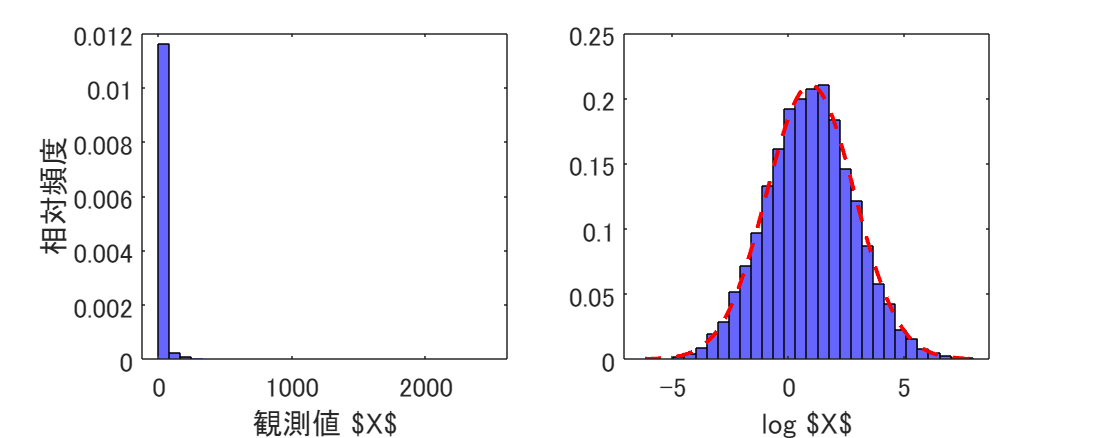

% フォントサイズを設定
set(0, 'DefaultAxesFontSize', 14);

% 対数正規分布のパラメータ
sigma = 0.954;
mu = exp(0.65);

% サンプルを生成
rng(0); % 乱数のシードを設定（再現性のため）
lognorm_samples = lognrnd(sigma, mu, [10000, 1]); % サンプルを生成
log_lognorm_samples = log(lognorm_samples); % 対数変換

% データを正規分布でフィット
pd = fitdist(log_lognorm_samples, 'Normal');
lognorm_mu = pd.mu; % 平均
lognorm_std = pd.sigma; % 標準偏差

% ヒストグラムとフィット結果をプロット
figure; % 図の作成

% 対数正規分布
subplot(1, 2, 1);
histogram(lognorm_samples, 30, 'Normalization', 'pdf', 'FaceColor', 'blue', 'EdgeColor', 'black');
xlabel('観測値 $X$'); % x軸ラベル
ylabel('相対頻度'); % y軸ラベル

% 対数変換後の対数正規分布
subplot(1, 2, 2);
histogram(log_lognorm_samples, 30, 'Normalization', 'pdf', 'FaceColor', 'blue', 'EdgeColor', 'black');
x = linspace(min(log_lognorm_samples), max(log_lognorm_samples), 1000);
hold on;
plot(x, normpdf(x, lognorm_mu, lognorm_std), 'r--', 'LineWidth', 2); % 正規分布を描画
xlabel('log $X$'); % x軸ラベル
hold off;

% レイアウトの設定
set(gcf, 'Position', [100, 100, 1000, 400]);
set(gcf, 'PaperPositionMode', 'auto');
print(gcf, '../figures/3_1_3_3_log_transform.png', '-dpng', '-r300'); % 画像として保存

### 図 3.1.4 様々な理論分布

### 図 3.1.5 累積分布でデータを見る

% サイコロをn回振った時の出目の総和をrepeat回サンプリングする関数

function sums = roll_dice(n, repeat)
    if nargin < 2
        repeat = 100; % デフォルトのrepeat回数
    end
    if nargin < 1
        n = 100; % デフォルトのn回数
    end
    sums = sum(randi(6, n, repeat));
end